# Atividade 10_02

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Rotulação e propriedades de componentes conexos em imagens binárias  

Obtenha um histograma das áreas das células da imagem whitecells4.png. Importante: um “histograma das áreas das células” não é um plot de célula no eixo x e área da respectiva célula no eixo y, mas sim: área no eixo x e quantidade (contagem) de células com a respectiva área no eixo y. Portanto, as áreas devem ser discretizadas em faixas de valores (ranges), para que cada faixa seja representada por um bin do histograma. Este processo é denominado binning. Dica: função histogram(X,nbins)

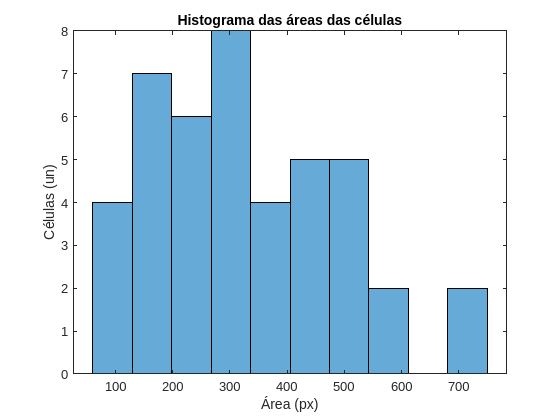

img = imread("whitecells4.png");

th = graythresh(img);
bw = imbinarize(img, th);

[rv, nlabels] = bwlabel(bw, 8);

area = zeros(1, nlabels);
linearIdx = cell(1, nlabels);

for k = 1:nlabels
    linearIdx{k} = find(rv == k);
    area(k) = length(linearIdx{k});
end

figure, histogram(area, 10)
xlabel("Área (px)")
ylabel("Células (un)")
title("Histograma das áreas das células")